# 中山大学电子与通信工程学院

# 《数字信号处理实验》实验报告

姓名：    王晨晖      学号：   24307163      专业：  电子信息工程    

## 实验七 GPS信号的捕获

## 一、实验目的

- **了解GPS信号接收处理过程**

- **掌握GPS****信号数字正交解调方法**

- **掌握面向实际信号的FIR****滤波器设计方法**

- **掌握GPS****信号多普勒搜索方法**

- **掌握GPS****信号的相关接收和捕捉方法**

## 二、实验要求

- **每个实验内容都要清晰展示实验过程和实验结果。**

- **绘图时必须明确标出各个坐标轴的意义和单位。**

- **绘制多个子图时要明确标出各个子图所画的内容。**

- **绘制多个信号时采用不同的线型和颜色区分、添加图例。**

- **严禁抄袭、复制，发现雷同报告或代码双方成绩均作废！！**

## 三、实验原理

1 相关函数与卷积

- 互相关函数衡量两个信号之间的相似程度，反映信号 x(n) 与时移后的 y(n-m) 之间的匹配程度，定义为对所有 n 求 x(n) 与 y(n-m) 乘积之和

- 自相关函数是互相关的特殊情形，即将信号与其自身进行相关运算，用于描述信号本身的周期性和相似结构

- 线性卷积定义为：z(n) 等于对所有 k 求 x(k) 与 y(n-k) 乘积之和，描述两个信号叠加后的响应

- 相关与卷积的关系：将 y(n) 先做翻转得到 y(-n)，再与 x(n) 做卷积，结果等价于 x 与 y 的互相关运算，因此可通过 `flip` + `conv` 来替代 `xcorr`

2 GPS C/A 码（Gold 码）特性

- GPS 扩频码采用 C/A 码，由两个 10 级线性反馈移位寄存器（LFSR）生成的 Gold 码构成

- 码长为 1023 chips，码率为 1.023 MHz，每个完整周期为 1 ms

- 生成方式：C/A = G1 XOR G2(shifted)，G1 反馈多项式为 1+x^3+x^10，G2 反馈多项式为 1+x^2+x^3+x^6+x^8+x^9+x^10

- 不同卫星通过对 G2 码施加不同相位偏移加以区分，实现码分多址（CDMA）

- 良好的自相关性：自相关峰值为 1023，旁瓣极小，接近理想冲激响应，便于精确定时

- 低互相关性：不同 PRN 卫星的 C/A 码互相关幅度约为 -1/1023，各卫星信号互不干扰

3 GPS 中频信号结构与频谱分析

- GPS 射频信号经下变频后得到中频（IF）信号，中频频率为 9.548 MHz，采样频率为 38.192 MHz

- 中频信号频谱包含两部分：中频附近的 GPS 扩频信号分量（带宽约 2 MHz），以及零频处的直流（DC）分量

- 去直流处理：将信号减去其均值，消除 DC 偏置，避免频谱中出现零频尖峰干扰后续分析

- DFT 频谱计算：对信号进行快速傅里叶变换（FFT），点数 N 决定频率分辨率，分辨率 = 采样频率 / N

- 调用 `fftshift` 将零频移至频谱中心，得到以零频为对称轴、范围为 (-fs/2, fs/2) 的双边频谱

4 FIR 低通滤波器设计（窗函数法）

- 正交解调后的复基带信号中仍残留 2 倍中频处的杂散分量，需通过**低通滤波器（LPF）**滤除

- FIR 低通滤波器的理想频率响应为：通带内增益为 1，阻带内增益为 0，以截止频率 wc 为分界

- 理想冲激响应为 sinc 函数，长度无限，实际工程中采用窗函数法将其截断为有限长度

- 窗函数法原理：将理想冲激响应 hd(n) 与窗函数 w(n) 相乘，得到实际可实现的 FIR 滤波器系数 h(n)

- 本实验使用 `fir1` 函数（默认 Hamming 窗）设计 1000 阶 FIR 低通滤波器，截止频率为 2 MHz，对应归一化截止频率约为 0.1048（= 2 MHz / (38.192/2) MHz）

5 正交解调（IQ Demodulation）

- 正交解调将中频信号与本地同频复载波相乘，将信号从中频搬移至零频基带

- 本地复载波由同相分量 cos(2*pi*f_local*n*Ts) 和正交分量 j*sin(2*pi*f_local*n*Ts) 构成

- f_local 为本地振荡频率，覆盖多普勒偏移的搜索范围；Ts = 1/fs 为采样间隔

- 相乘后的复信号经低通滤波去除 2 倍载频处的分量，得到纯基带 IQ 复信号，供后续相关捕获使用

6 GPS 信号捕获：频域相关法

- GPS 信号捕获需同时搜索两个未知量：码相位（C/A 码的对齐位置）和多普勒频偏（搜索范围 ±7 kHz，步进 500 Hz）

- 频域相关法：先对基带信号和本地 C/A 码分别做 FFT，再将两者频域结果相乘（取本地码的共轭），最后 IFFT 得到循环相关序列，相当于对所有码相位偏移同时进行匹配滤波

- 相比时域逐点相关的 O(N^2) 复杂度，频域法将计算量降至 O(N*logN)，大幅提升搜索速度

- 对本地 C/A 码频谱取共轭，在频域等效于时域翻转，从而实现匹配滤波效果

- 捕获判决准则：计算最大相关峰与次级峰的幅度之比，若该比值超过门限 sqrt(2.5)，则判定该卫星在当前频点被成功捕获

- 为防止主瓣干扰次级峰的搜索，在定位次级峰前将最大峰周围 ±38 个采样点清零

## 四、实验所用MATLAB函数

- `xcorr(x, y)` — 计算两序列的互相关函数（令 x=y 则为自相关），返回长度为 2N-1 的相关序列

- `conv(x, y)` — 计算两序列的线性卷积，返回长度为 Nx+Ny-1 的序列

- `flip(y)` — 翻转向量或矩阵的元素顺序，用于将卷积转换为相关运算

- `fft(x)` / `fft(x, N)` — 计算信号的快速傅里叶变换，可指定点数 N（补零）以细化频率分辨率

- `ifft(X)` — 计算离散傅里叶逆变换，将频域乘积结果还原为时域相关序列

- `fftshift(X)` — 将 FFT 输出的零频分量移至频谱中心，便于可视化双边频谱

- `fir1(N, Wn, 'low')` — 用窗函数法设计 N 阶线性相位 FIR 低通滤波器，Wn 为归一化截止频率

- `freqz(b, 1, npts)` — 计算 FIR 滤波器的频率响应，返回幅频特性 H 及对应归一化频率向量 W

- `filter(b, 1, x)` — 用 FIR 滤波器系数 b 对输入信号 x 进行时域滤波

- `mean(x)` — 计算序列算术平均值，用于去除信号中的直流（DC）偏置分量

- `abs(x)` — 计算复信号的模（幅度），用于求频谱幅度或相关结果的包络

- `conj(X)` — 计算复数的共轭，频域相关法中对本地码频谱取共轭以实现匹配滤波

- `max(x)` — 返回序列的最大值及其下标，用于定位相关峰值和码相位偏移量

- `stem(n, x)` — 绘制离散序列的火柴棍图，适合展示滤波器系数等离散时域信号

- `plot(x, y)` / `subplot` — 绘制连续曲线；subplot 在同一窗口创建多个子图，用于对比展示

- `load('filename.mat')` — 加载 .mat 数据文件，导入 longSignal、BasebandSignalPRN、caCodesTable 等实验数据

## 五、实验内容、方法、代码与结果

## (一)相关的定义与计算

### （1）互相关函数

`    互相关是用来表示两个信号之间相似性的一个度量，是两个信号之间相对于时间的一个函数。信号`$x\left(n\right)$`和`$y\left(n\right)$`的互相关函数定义为`


$$r_{\textrm{xy}} \left(m\right)=\sum_{n=-\infty }^{\infty } x\left(n\right)y\left(n-m\right)$$


$x\left(n\right)$`保持不动，`$y\left(n\right)$`右移`m`个采样周期得到`$y\left(n-m\right)$，`再将`$x\left(n\right)$`与`$y\left(n-m\right)$`相乘并求和，则得到`$r_{\textrm{xy}} \left(m\right)$`在`$m$`时刻的值。`$r_{\textrm{xy}} \left(m\right)$`反映了`$x\left(n\right)$`与`$y\left(n-m\right)$`两个波形的相似程度。`

### （2）自相关函数

   `自相关是一个信号与其自身在不同时间点的互相关，即互相关函数的定义式中，如果`$y\left(n\right)=x\left(n\right)$`则得到自相关函数`


$$r_{\textrm{xx}} \left(m\right)=\sum_{n=-\infty }^{\infty } x\left(n\right)x\left(n-m\right)$$


`自相关函数表示了信号`$x\left(n\right)$`与自身移位后的`$x\left(n-m\right)$`的相似程度。为了表示简单，一般将自相关函数记为`$r_x \left(m\right)$`。`

`    在实际应用中，输入序列是有限长序列，或只能获得无限长序列的有限个序列值，则相关函数的有限和形式可以表示为    `


$$r_{x y}(m)=\left\{\begin{array}{ll}
\sum_{n=m}^{N-1} x(n) y(n-m) & 0<m \leq N \\
\sum_{n=0}^{N-|m|-1} x(n) y(n-m) & -N<m<0 \\
0 & m \text { 为其他值 }
\end{array}\right.$$


`上述对相关函数的定义都是针对实信号的，如果`$x\left(n\right)$`和`$y\left(n\right)$`是复信号，其相关函数也是复信号，此时互相关和自相关定义式应该为`


$$r_{\textrm{xy}} \left(m\right)=\sum_{n=-\infty }^{\infty } x\left(n\right)y^* \left(n-m\right)$$



$$r_x \left(m\right)=\sum_{n=-\infty }^{\infty } x\left(n\right)x^* \left(n-m\right)$$


如果是频域实现相关，则公式为：


$$r_{\textrm{xy}} \left(m\right)=\textrm{IDFT}\left(\textrm{DFT}\left(x\left(n\right)\right)\times {\textrm{DFT}\left(y\left(n\right)\right)}^* \right)$$


即两个信号的频域相乘，注意其中参考信号（本地信号，对应本试验为C/A码信号）要取共轭。

### （3）卷积

`    卷积的定义为`


$$x\left(n\right)\ast y\left(n\right)=\sum_{m=-\infty }^{\infty } x\left(m\right)y\left(n-m\right)$$


`可以发现，相关函数的定义与卷积非常像，两者有如下转换关系：`


$$\begin{array}{l}
r_{\textrm{xy}} \left(m\right)=\sum_{n=-\infty }^{\infty } x\left(n\right)y\left(n-m\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;=\sum_{n=-\infty }^{\infty } x\left(n\right)y\left\lbrack -\left(m-n\right)\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;\;=x\left(n\right)\ast y\left(-n\right)|_{n=m} 
\end{array}$$


   `与序列卷积运算相比较，相关运算仅缺少了将`$y\left(n\right)$`翻转成`$y\left(-n\right)$`的步骤，其他运算完全相同。因此，用于卷积的计算过程和程序都可以直接用于计算序列的相关函数。`

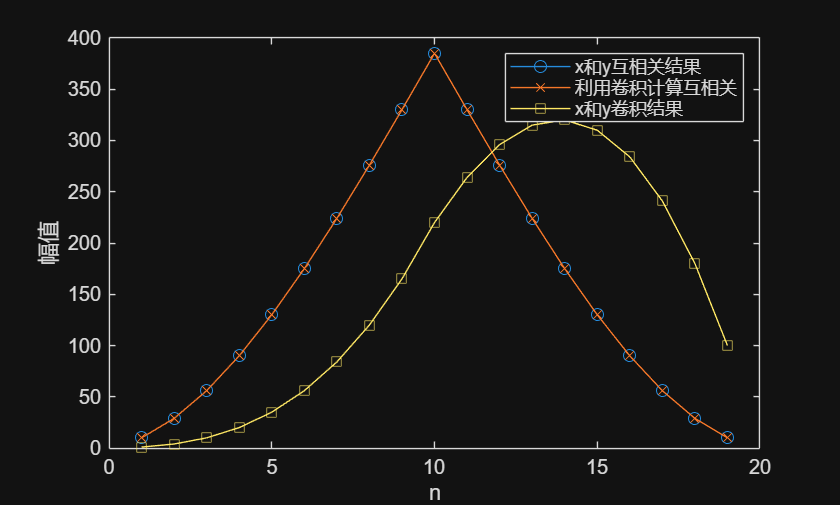

clc;clear all; close all;
x=1:10;%
y=1:10;
%%%题目1.1调用xcorr求x和y的相关函数
                            %%%求x和y的相关
Rxy = xcorr(x,y);

%%%题目1.2调用conv求x和y的相关，注意y应该做翻转；
                            % 为了用卷积实现相关，可以把信号进行翻转，由于卷积运算还要翻转一次，所以两次翻转后就变成了相关。flip 翻转元素顺序
Rxy_conv = conv(x,flip(y));
%%%题目1.3调用conv直接求x和y的卷积
                            %%%求x和y的卷积
xy_conv = conv(x,y);
%%%题目1.4,在一张图里面画出x和y的相关函数、用卷积求相关、以及直接求卷积三种情况的图像。
figure;
plot(Rxy,'-o');hold on;
plot(Rxy_conv,'-x');
plot(xy_conv,'-s');
xlabel('n');ylabel('幅值');
legend('x和y互相关结果','利用卷积计算互相关','x和y卷积结果');

## （二）GPS信号的捕获

### （1）定义      

       `全球定位系统（英文：`Global Positioning System，GPS`），是一种以人造地球卫星为基础的高精度无线电导航的定位系统，它在全球任何地方以及近地空间都能够提供准确的地理位置、车行速度及精确的时间信息。`GPS `卫星信号是` GPS `卫星向广大用户发送的` PSK `调制波。利用该信号，用户可以实时、全天候的实现三维导航和定位。`

### （2）特征

       `卫星所发射的信号可分为三个层次：``载波(`Carrier signal`)、伪码(`PRN code`)和数据码(`Navigation message`)``。在这三个层次中，伪码和数据码一起先通过调制依附在正弦波形式上的载波，然后卫星将调制后的载波信号发射出去。因此，载波可以说是卫星信号中的最底层。`

    GPS`卫星所用的载波有两个, 由于它们均位于微波的`$L$`波段，故分别称为`$L_1$`载波和`$L_2$`载波。其中`$L_1$`载波是由卫星上的原子钟所产生的基准频率`$f_0 \left(f_0 =10\ldotp 23\textrm{MHz}\right)$` 倍频`154`倍后形成的, 即`$f_1 =154\times f_0 =1575\ldotp 42\textrm{MHz}$` , 其波长`$\lambda_1$`为`$19\ldotp 03\textrm{cm}$`; `$L_2$`载波是由基准频率`$f_0$`倍频`120`倍后形成的, 即`$f_2 =120\times f_0 =1227\ldotp 60\textrm{MHz}$`, 其波长`$\lambda_2$`为`$24\ldotp 42\textrm{cm}$`,而选择`$L_1$`和`$L_2$`两个载波的目的在于测量出或消除掉由电离延迟误差。其中，`$L_1$`频段上调制了`C/A`码和`P(Y)`码，`$L_2$`频段上调制了`P(Y)`码；`C/A`码对普通用户开放，`P(Y)`码只对授权用户开放。美国政府规定，`P `码专为美国军方使用，商业用户只提供`C/A`码定位方式，故这里主要研究`C/A`码。`

`参数设置:`

samplingFreq=38192000;  %采样频率38.192MHz
codeFreqBasis=1023000;  %GPS信号码率1.023MHz
codeLength=1023;        %GPS信号码长，每个C/A码码长是1023位
ts = 1 / samplingFreq;  %采样间隔
IF=9548000;             %中频本振信号频率
samplesPerCode = round(samplingFreq/(codeFreqBasis/codeLength));%每个码的采样点数

### （3）C/A码

        C/A`码是用于分址、搜捕卫星信号和粗测距。它是具有一定抗干扰能力的``明码``，提供给民用。它是由两个`10`级反馈移位寄存器相结合而产生的。两个移位寄存器于每星期日子夜零时，在置“`1`”脉冲的作用下全部处于“`1`”状态，同时在`1.023MHz `时钟的驱动下，两个移位寄存器分别产生``两个伪随机码序列`$G_1 \left(t\right)$`和`$G_2 \left(t\right)$`，他们的码长均为`$N=2^{10} -1=1023$，`周期为`1ms`。`$G_2 \left(t\right)$`的输出不是该移位寄存器的最后一个存储单元，而是选择`$G_2 \left(t\right)$` 序列中的``某两个存储单元的输出进行模2 相加后输出``，由此得到一个与`$G_2 \left(t\right)$`平移等价的伪随机码序列，然后与`$G_1 \left(t\right)$`序列模` 2 `加，便得到结构不同的`C/A`码序列，亦称为` GOLD `码。由于`$G_2 \left(t\right)$`的码元共有`1023`位，故`$G_2 \left(t\right)$`可能有`1023`种平移等价序列，这`1023`种平移等价序列与`$G_1 \left(t\right)$`模`2`相加，可能产生`1023`种`m`序列，这些不同结构的伪随机码（`PRN`），称为一组` C/A `码。`

`    从这些伪随机码序列中选择不同的码序列以`PRN1，PRN2...`命名不同的` GPS`卫星，这样就使得不同的 `GPS `卫星采用结构相异的`C/A `码。这组`C/A `码的码长、周期和数码均相同。我们可以在本地用卫星所采用的多个`C/A`码生成本地信号，与接收到的卫星信号做相关，就可以根据相关峰值检测出信号中存在那几颗卫星，另外，还可以根据峰值位置（时刻）完成测距。`

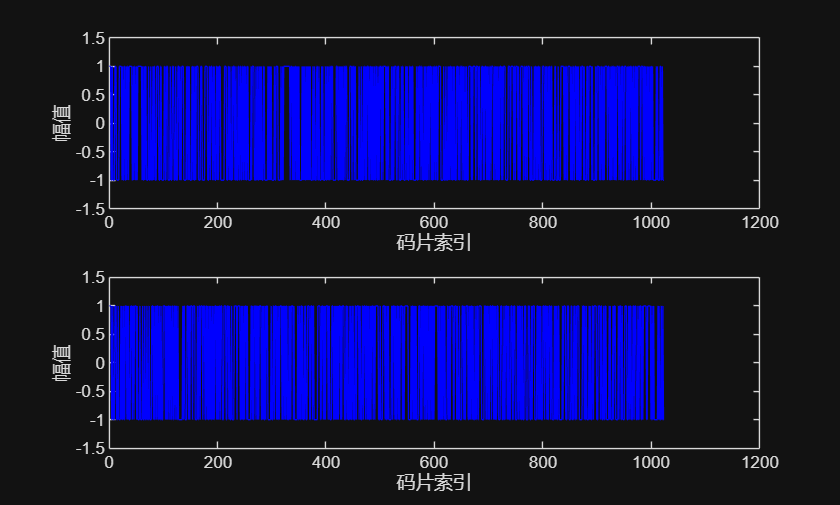

%--- 生成10ms的C/A码序列用于该PRN ---------------------
PRN=2;
caCode1 = generateCAcode(PRN);
PRN=3;
caCode2 = generateCAcode(PRN);
%%%题目2.1 画出cacode1和caCode2的图像；
figure;
subplot(2,1,1);
plot(caCode1,'b');
ylim([-1.5,1.5]);
xlabel('码片索引');ylabel('幅值');
subplot(2,1,2);
plot(caCode2,'b');
ylim([-1.5,1.5]);
xlabel('码片索引');ylabel('幅值');

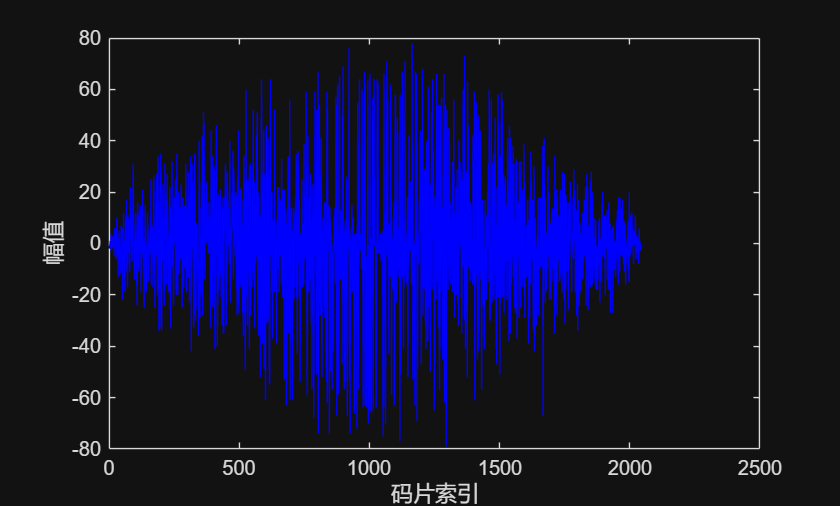

%%%题目2.2 求cacode1和caCode2的互相关，并画图；
RcaCode12 = xcorr(caCode1,caCode2);
figure;
plot(RcaCode12,'b');
xlabel('码片索引');ylabel('幅值');

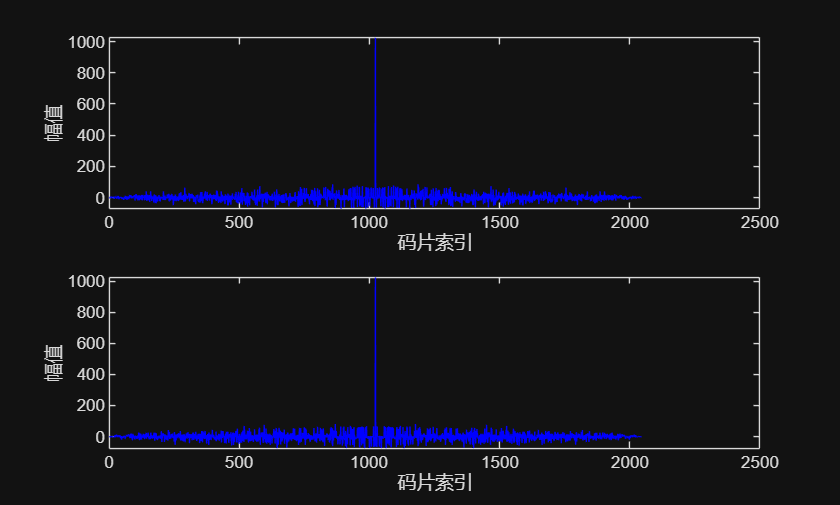

%%%题目2.3 分别求cacode1和caCode1的自相关，并画图；
RcaCode11 = xcorr(caCode1,caCode1);
RcaCode22 = xcorr(caCode2,caCode2);
figure;
subplot(2,1,1);
plot(RcaCode11,'b');
xlabel('码片索引');ylabel('幅值');
subplot(2,1,2);
plot(RcaCode22,'b');
xlabel('码片索引');ylabel('幅值');

### （4）基于线性卷积和快速卷积的GPS信号的捕获

#### （a）原理分析

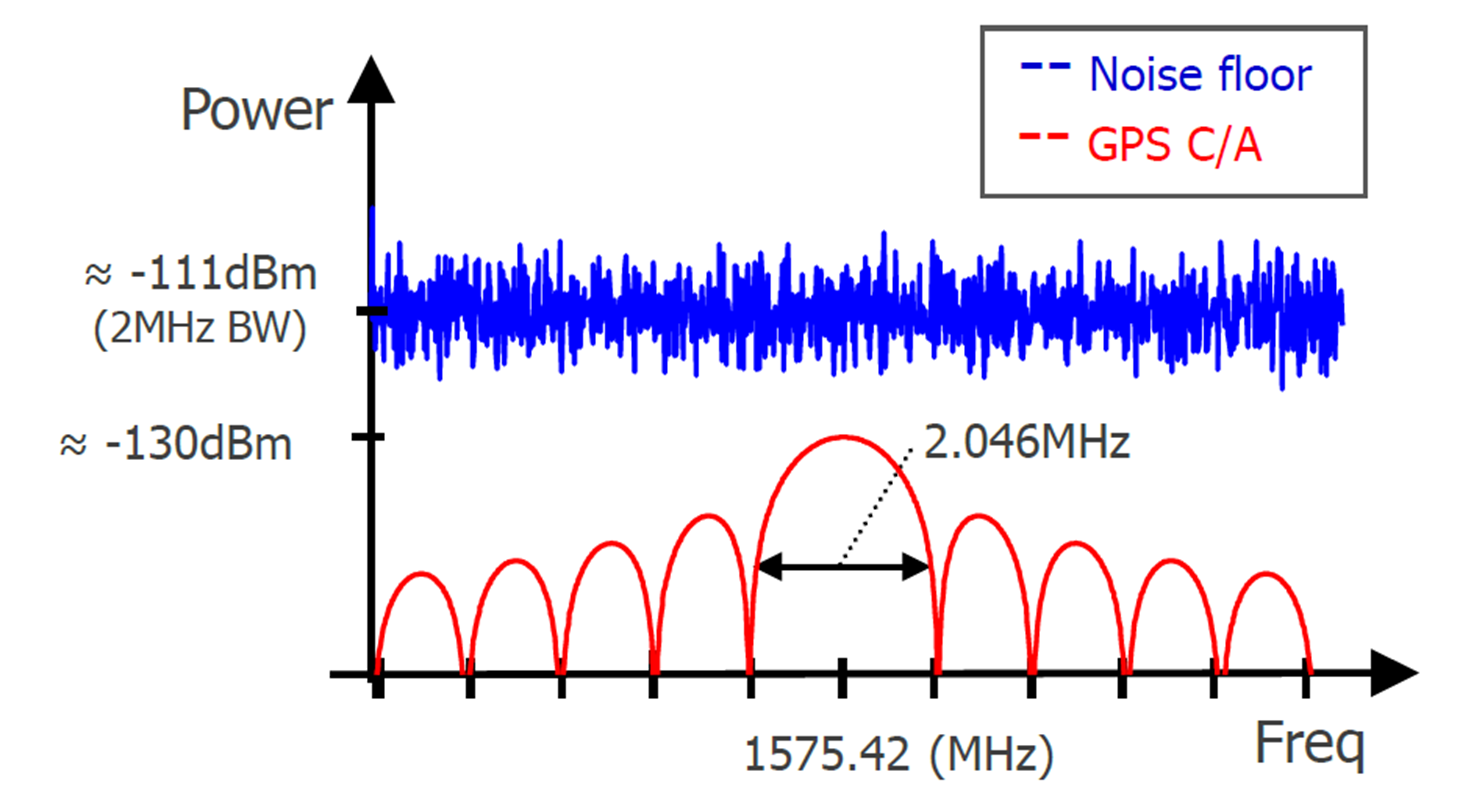

`GPS信号和噪声功率谱密度`

`    上图为我们展示了`GPS`信号在接收时的功率谱密度比噪声的功率谱密度少了近`20$\textrm{dB}$`（也即`100`倍），如此微弱的`GPS`信号会被直接淹没在噪声中。`

    `接收信号``：`


$$r\left(t\right)=\sqrt{C}D\left(t-\tau \right)x\left(t-\tau \right)\cos \left(2\pi \left(f_{\textrm{IF}} +f_D \right)t+\delta \theta \right)+n\left(t\right)$$


`    其中`$D\left(t-\tau \right)$包括了电文信息。

`    本地信号``：`


$$s_{\textrm{Ref}} \left(t\right)=x\left(t-\tau^{\prime } \right)\cos \left(2\pi \left(f_{\textrm{IF}} +{f_D }^{\prime } \right)t\right)$$


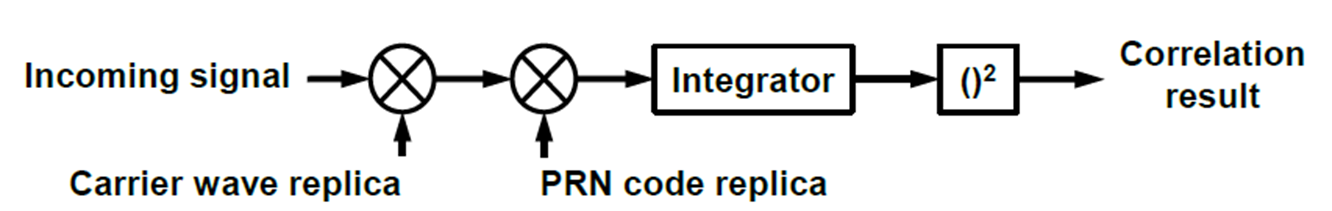

GPS`信号接收原理框图`

`    现在我们把`GPS`信号的捕获看成是一个系统，本地参考信号看成是系统的单位响应`$h\left(n\right)$`，对`GPS`信号`$r\left(n\right)$`的捕获过程就可以看成是接收信号经过系统之后的响应。亦即`


$$y\left(n\right)=h\left(n\right)\ast r\left(n\right)$$


`由于`GPS`信号是连续不断的，因此这就是典型的长信号卷积。长信号卷积可以直接采用实时卷积运算，即信号不断进入接收机，不断与接收机的响应进行加权求和，即进一个点，就利用卷积和出一个点。不过运算量比较大，一个点的运算需要进行N次乘法和N-1次加法（N为h(n)长度）。因此也可以采用FFT快速算法实现卷积运算。因此我们做两种算法，一个是卷积（相关）运算；一个是分段截取，然后FFT+频域相乘+IFFT算法。`

#### （b）GPS信号频谱分析    

`    对接收的GPS信号进行频谱分析，可以看到存在比较大的直流分量，将直流分量去掉之后，可以看到GPS信号的频谱，由于采样的信号是实信号，因此频谱是双边谱，并且因为采样得到的信号是中频信号，因此我们可以看到谱的中心在±9.58MHz附近。相关的图形显示如下：`

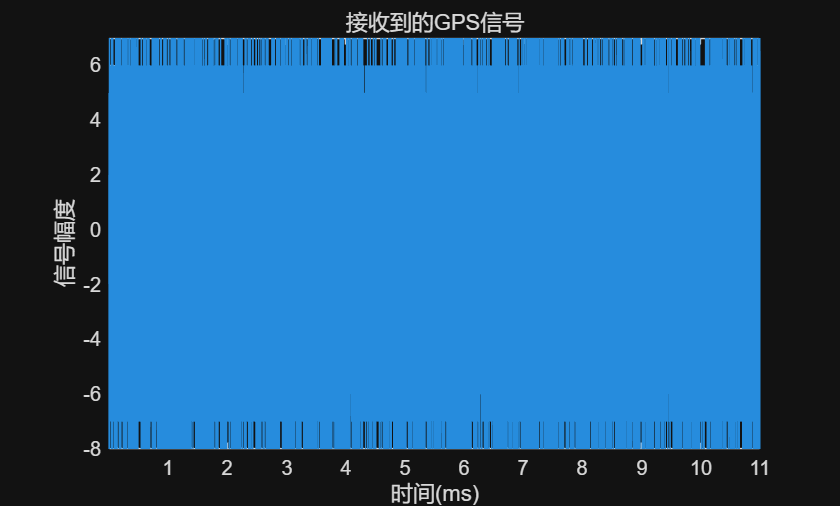

load longSignal.mat   %%%这个信号是中频采样信号，长度大概是11ms。
Len = length(longSignal);
tin = (1:Len)*ts*1e3;
fin = (-Len/2+1:Len/2)/Len*samplingFreq/1e6;  %%%单位MHz
figure
plot(tin,(longSignal))
xlabel('时间(ms)')
ylabel('信号幅度')
axis tight
title('接收到的GPS信号')

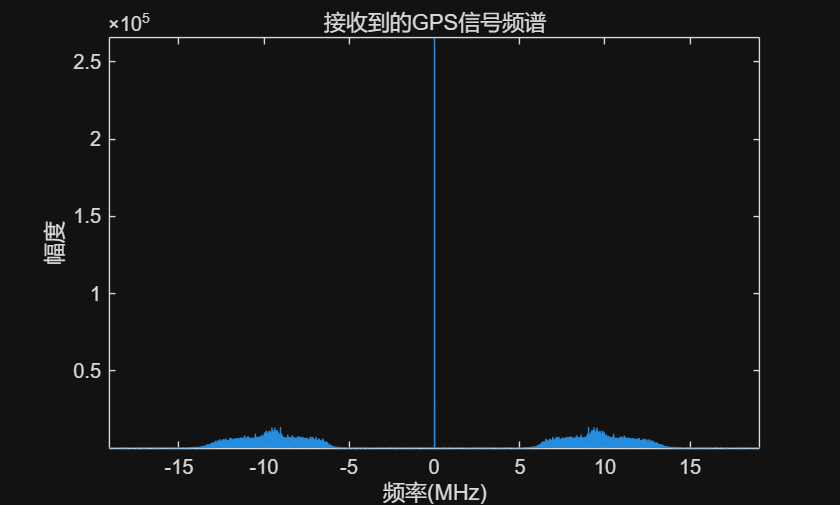

%%%题目3.1 请求上述信号的幅度谱，并画图，横坐标范围（-fs/2，fs/2），请注意做完FFT后，频率范围是0到fs/2，-fs/2到0.
figure;
plot(fin,abs(fftshift(fft(longSignal))));
xlabel('频率(MHz)');
ylabel('幅度');
axis tight;
title('接收到的GPS信号频谱');

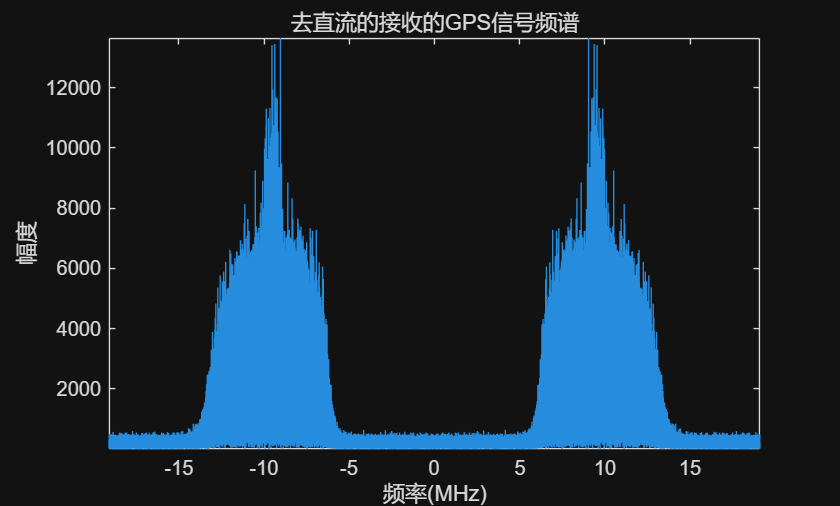

%%%题目3.2观察上述频谱，我们发现0频处存在一个很高的分量，那是信号中存在直流分量。请消除0频分量（可以采用减掉信号平均值的方法），然后再画图。
longSignal_noDC = longSignal - mean(longSignal);
figure;
plot(fin,abs(fftshift(fft(longSignal_noDC))));
xlabel('频率(MHz)');
ylabel('幅度');
axis tight;
title('去直流的接收的GPS信号频谱');

#### （c）GPS信号接收处理    

- `分析信号频谱，设计滤波器，实现基带信号滤波。`

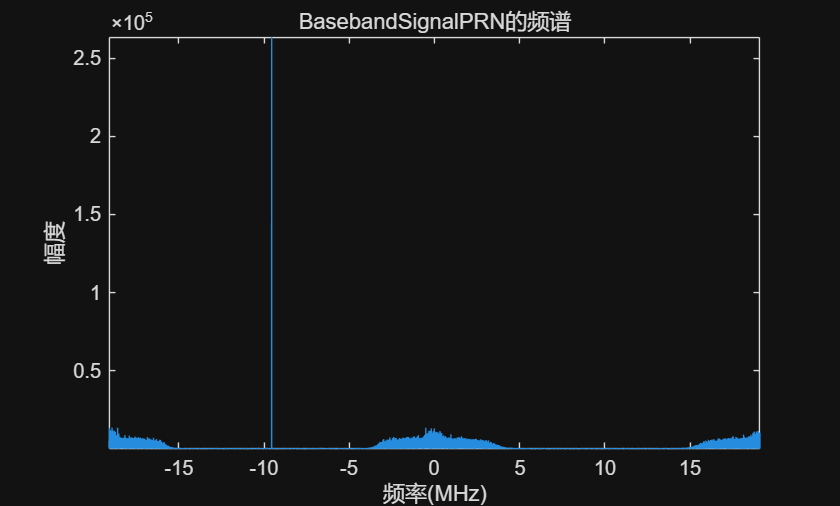

load BasebandSignalPRN.mat  %%%这个信号是正交解调后的复信号,长度也是11ms。
%%%题目3.3 画出变量BasebandSignalPRN的频谱，观察它的频谱分量，注意横坐标范围（-fs/2，fs/2），请注意做完FFT后，频率范围是0到fs/2，-fs/2到0。
%我们发现，这个信号并非理想的基带信号，它包括基带信号分量，以及两倍中频分量，还有个搬移到中频的零频分量。中频为9.548MHz
LenBaseband = length(BasebandSignalPRN);
finBaseband = (-LenBaseband/2+1:LenBaseband/2)/LenBaseband*samplingFreq/1e6;  %%%单位MHz
figure;
plot(finBaseband,abs(fftshift(fft(BasebandSignalPRN))));
xlabel('频率(MHz)');
ylabel('幅度');
axis tight;
title('BasebandSignalPRN的频谱');

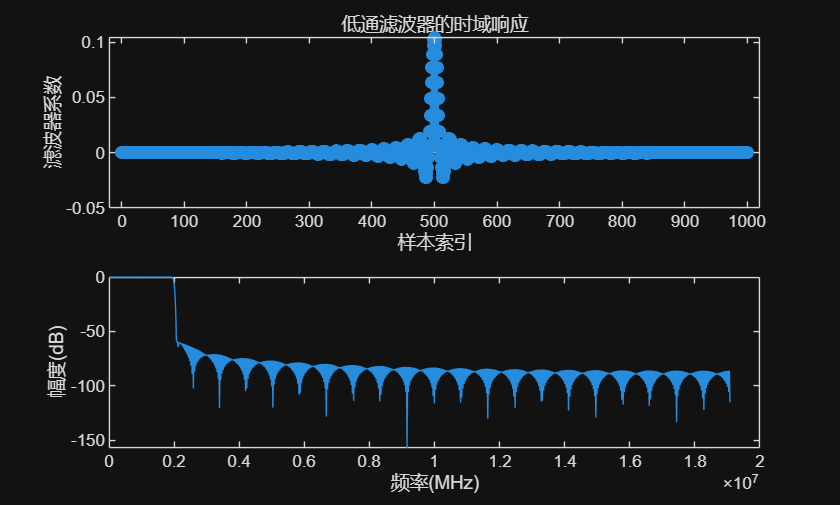

%%%%我们发现这个所谓的基带复信号其实并非"基带"，而是带有两倍中频分量。
%%%%%%%%%题目3.4 设计一个低通滤波器，将感兴趣的频谱（-2至2MHz）滤出来，滤除两倍中频分量和在中频位置零频分量，画出滤波器的时域和幅频响应曲线（dB显示）。
%设计一个低通滤波器，截止频率为2MHz，采样频率为38.192MHz，滤波器阶数为1000。
cutoffFreq = 2000000; % MHz
normalizedCutoffFreq = cutoffFreq / (samplingFreq/2); % 归一化截止频率
filterOrder = 1000; % 滤波器阶数
% 使用窗函数法设计低通滤波器
b = fir1(filterOrder, normalizedCutoffFreq, 'low');
% 画出滤波器的时域响应
figure;
subplot(2,1,1);
stem(0:filterOrder, b, 'filled');
xlabel('样本索引');ylabel('滤波器系数');
title('低通滤波器的时域响应');
% 画出滤波器的幅频响应
[H, W] = freqz(b, 1, 1024);
subplot(2,1,2);
plot(W/pi*samplingFreq/2, 20*log10(abs(H)));
xlabel('频率(MHz)');ylabel('幅度(dB)');

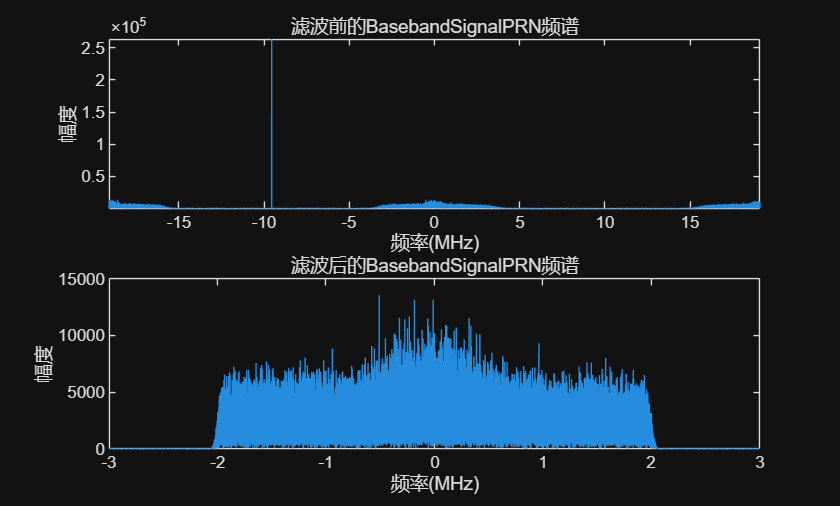


%%%%%滤波器设计完毕。
%%%题目3.5 对BasebandSignalPRN信号进行滤波处理，结果应该只剩下基带信号，画出滤波前后的频谱。
filteredSignal = filter(b, 1, BasebandSignalPRN);
figure;
subplot(2,1,1);
plot(finBaseband,abs(fftshift(fft(BasebandSignalPRN))));
xlabel('频率(MHz)');
ylabel('幅度');
axis tight;
title('滤波前的BasebandSignalPRN频谱');
subplot(2,1,2);
plot(finBaseband,abs(fftshift(fft(filteredSignal))));
xlim([-3,3]);
xlabel('频率(MHz)');
ylabel('幅度');
title('滤波后的BasebandSignalPRN频谱');

- ` 通过跟频域相乘法和卷积法进行相关处理，实现信号的相关运算，实现信号捕获和延时测量（峰值处即为）。`

C/A码周期为1 ms（对应距离约300 km），而卫星距地表平均约2万公里（传播时间约70 ms）。相关运算仅能确定不足1 ms的时间差小数部分（即不足一个整周期的偏移量），而整数周期数需结合导航电文中的时间信息解析。C/A相关抗噪能力更强，1us时间误差会导致300米距离误差，而C/A码码宽仅1μs，相关技术可将时间测量精度提升到码宽的1%左右，即3m左右。

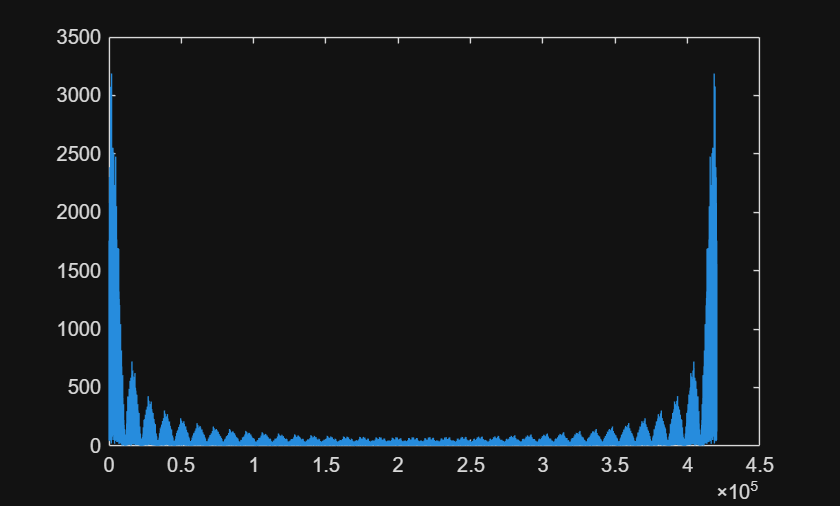

PRN=3;
load caCodesTable.mat   %%%
caCode=caCodesTable(PRN, :);
caCodeFreqDom=conj(fft(caCode,length(BasebandSignalPRN)));%%%%求本地C/A码信号的频谱并取共轭。
figure;plot(abs(caCodeFreqDom))

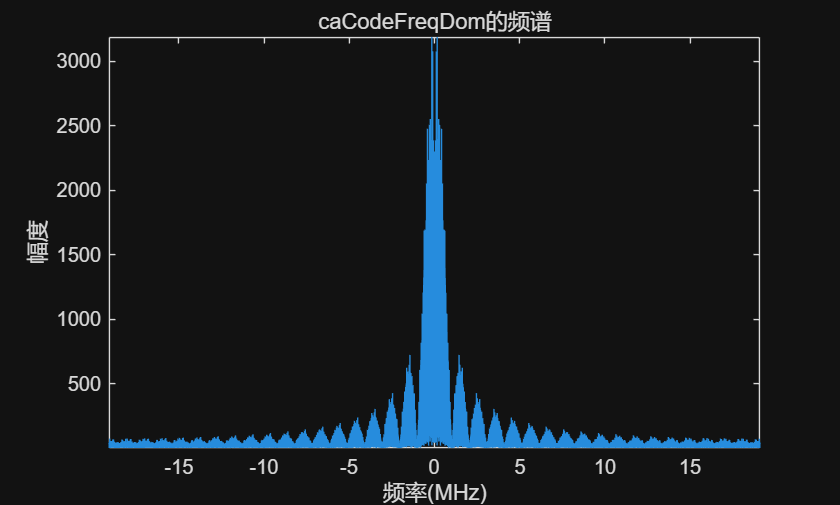

%%%%题3.6 画出caCodeFreqDom的频谱并观察，给出主瓣宽度（主瓣旁边两个零点之间的宽度），应该是2MHz左右。
figure;
plot(finBaseband,abs(fftshift(caCodeFreqDom)));
xlabel('频率(MHz)');
ylabel('幅度');
axis tight;
title('caCodeFreqDom的频谱');

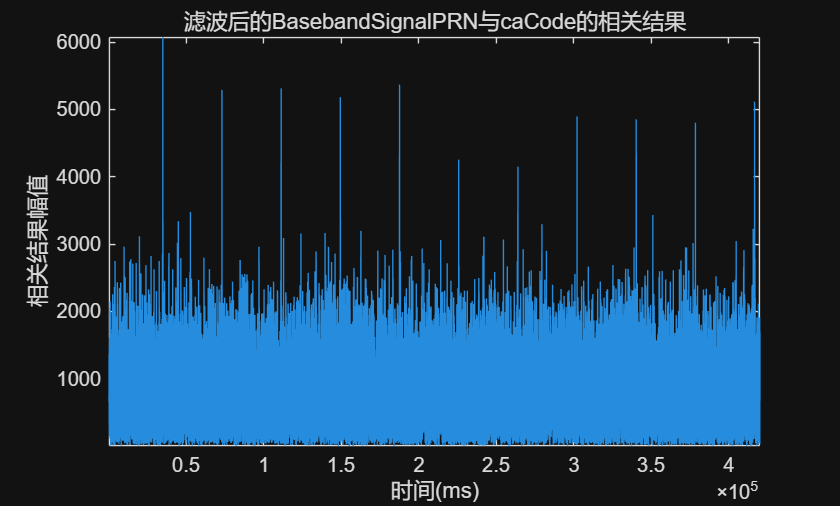

%%%%题3.7 对滤波后的BasebandSignalPRN信号进行相关处理并画图。采用频域共轭相乘再反变换的方法，注意本地信号caCode的求频谱后取共轭，并且求频谱的时候要补零到跟BasebandSignalPRN一样长，以保证后面两者相乘长度一致。
filteredSignalFreqDom = fft(filteredSignal);
correlationFreqDom = filteredSignalFreqDom .* caCodeFreqDom;
correlationTimeDom = ifft(correlationFreqDom);
figure;
plot(abs(correlationTimeDom));
xlabel('时间(ms)');
ylabel('相关结果幅值');
axis tight;
title('滤波后的BasebandSignalPRN与caCode的相关结果');

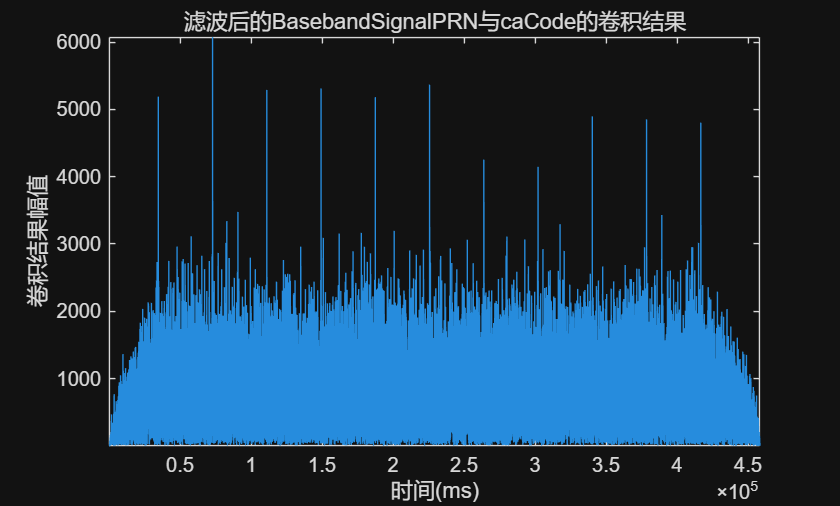

%%%%题3.8对滤波后的BasebandSignalPRN信号进行卷积处理(注意擦caCode信号要翻转)并画图。当然，也可以用相关的方法。比较两者结果，分析为何在两端存在差异。
convolutionResult = conv(filteredSignal, flip(caCode));
figure;
plot(abs(convolutionResult));
xlabel('时间(ms)');
ylabel('卷积结果幅值');
axis tight;
title('滤波后的BasebandSignalPRN与caCode的卷积结果');

## (d)不同卫星、不同多普勒的搜索

#### 本部分实现对不同卫星信号，不同多普勒的搜索。由于卫星和地面接收机都在运动，因此两者之间存在多普勒平移。也就是即使做了正交解调，也可能在接收到的信号中存在一个单频调制，这个单频调制会导致相关运算的峰值下降，严重时，会导致完全无法形成峰值。比如当多普勒频率等于1000Hz时，此时在1ms的时间内，刚好1个周期，相关运算是点乘后求和，那么求和的的结果理论上会是0，即完全抵消。因此我们要进行多普勒搜索。当多我们猜想的多普勒与实际一致时，相关运算会出现最大峰值。

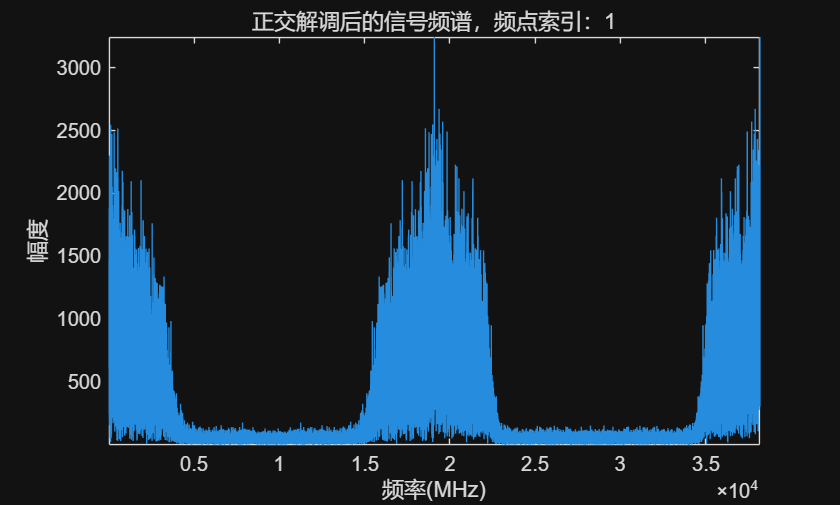

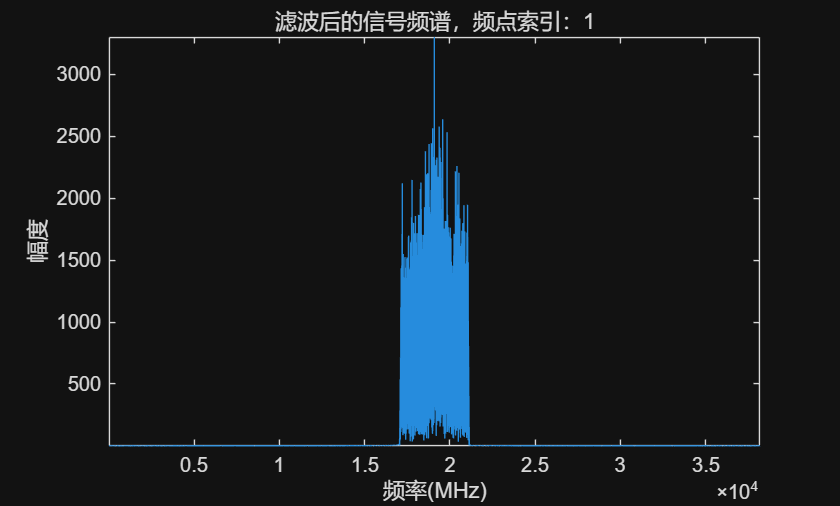

第03颗卫星的 

第18个频带捕获到信号 

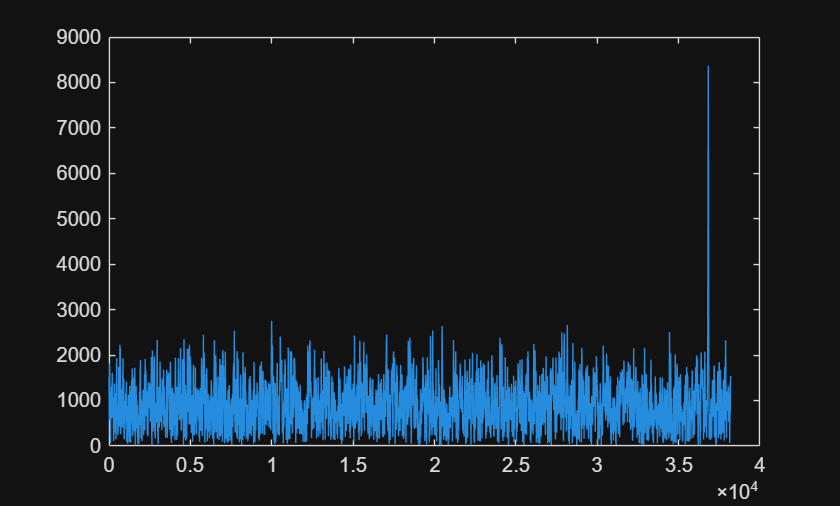

第03颗卫星的 

第19个频带捕获到信号 

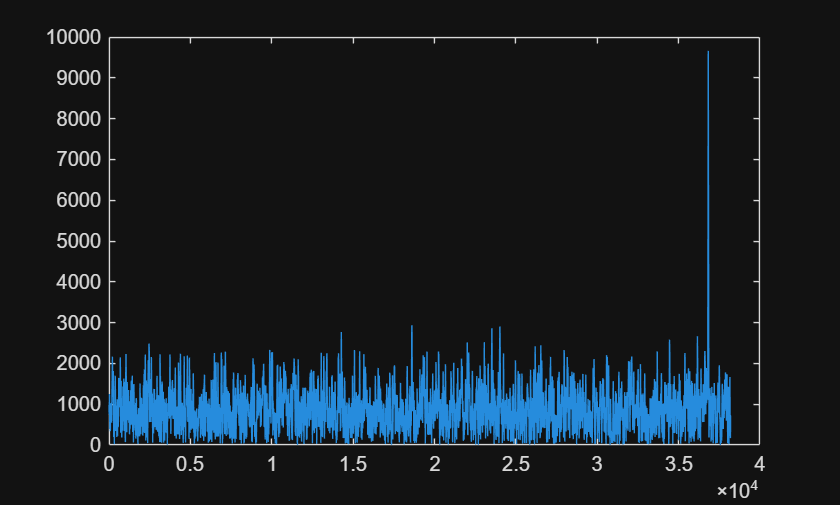

第06颗卫星的 

第07个频带捕获到信号 

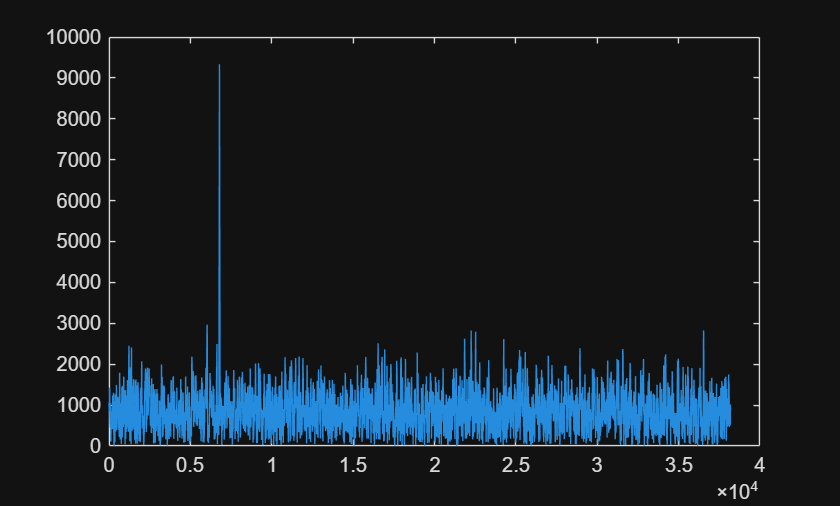

第06颗卫星的 

第08个频带捕获到信号 

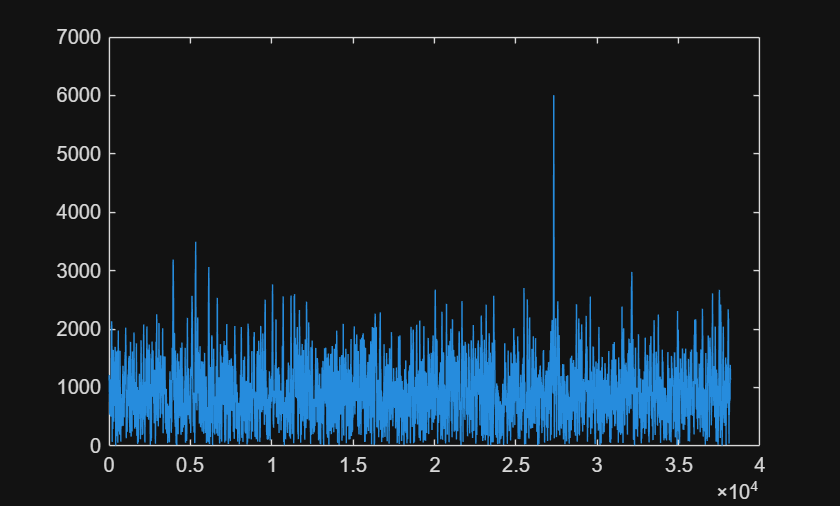

第09颗卫星的 

第20个频带捕获到信号 

第09颗卫星的 

第21个频带捕获到信号 

第15颗卫星的 

第18个频带捕获到信号 

第15颗卫星的 

第19个频带捕获到信号 

第18颗卫星的 

第15个频带捕获到信号 

第18颗卫星的 

第16个频带捕获到信号 

第18颗卫星的 

第27个频带捕获到信号 

第21颗卫星的 

第13个频带捕获到信号 

第21颗卫星的 

第14个频带捕获到信号 

第21颗卫星的 

第15个频带捕获到信号 

第22颗卫星的 

第17个频带捕获到信号 

第22颗卫星的 

第18个频带捕获到信号 

第22颗卫星的 

第19个频带捕获到信号 

第26颗卫星的 

第09个频带捕获到信号 

acqThreshold=sqrt(2.5);       %检测判决门限
longSignal=longSignal-mean(longSignal);%减去直流分量
signal1 = longSignal(1 : samplesPerCode);  %%%%取出1ms数据，只进行一次计算。
%%  下面定义频率搜索的范围，一共搜索29个频点，每个频点差500Hz，所以
%一共搜索28*500Hz
acqSearchBand =14;%捕获的频带宽度
numberOfFrqBins = round(acqSearchBand * 2) + 1;%搜索的频点，每个频点之间的差是500Hz
%%  载入CA码的码表，可以把CA码看成是系统的冲激响应h(n)

%% --- 初始化一些使用到的数组以加快运算速度 -------------------------------

for PRN=1:32   %%%不同卫星搜索
    caCodeFreqDom = conj(fft(caCodesTable(PRN, :),length(signal1)));%将序号为PRN的卫星参考信号通过DFT变换到频域，相当于得到h(n)对应的H(k)
    %--- Make the correlation for whole frequency band (for all freq. bins)
    for frqBinIndex = 1:numberOfFrqBins   %%%不同的多普勒的搜索

        %--- Generate carrier wave frequency grid (0.5kHz step) -----------
        frqBins(frqBinIndex) = IF - (acqSearchBand/2) * 1000 + 0.5e3 * (frqBinIndex - 1); %%%中频信号减去多普勒频率，后面用这个频率进行正交解调，去除多普勒的影响。
       
        %--- Generate local sine and cosine -------------------------------
      
       %%%%题目4.1 产生本地正弦和余弦信号，完成对signal1信号的正交解调，并形成复信号，是否存在2倍中频分量。
        t = (0:length(signal1)-1) * ts; % 时间向量
        localSine = sin(2*pi*frqBins(frqBinIndex)*t); % 本地正弦信号
        localCosine = cos(2*pi*frqBins(frqBinIndex)*t); % 本地余弦信号
        signalIQ = signal1 .* (localCosine + 1j*localSine); % 正交解调后的复信号
       
        if(frqBinIndex==1 && PRN==1) %%%只画出第一个频点，第一个卫星的结果
        figure;
        plot(abs(fftshift(fft(signalIQ))));
        xlabel('频率(MHz)');
        ylabel('幅度');
        axis tight;
        title(['正交解调后的信号频谱，频点索引：', num2str(frqBinIndex)]);
        end
       %%%%题目4.2 利用之前设计的低通滤波其完成对signal1信号的滤波,观察频谱是否只剩下低频分量。
        signalIQ_filtered = filter(b, 1, signalIQ);
        if(frqBinIndex==1 && PRN==1) %%%只画出第一个频点，第一个卫星的结果
        figure;
        plot(abs(fftshift(fft(signalIQ_filtered))));
        xlabel('频率(MHz)');
        ylabel('幅度');
        axis tight;
        title(['滤波后的信号频谱，频点索引：', num2str(frqBinIndex)]);
        end
       %%%%题目4.3 利用频域共轭相乘方法完成相关运算。
        % acqRes1 = abs(ifft(convCodeIQ1)) .^ 2; %%%%相关结果
        % temp=acqRes1;
        signalIQ_filtered_freqDom = fft(signalIQ_filtered);
        correlationFreqDom = signalIQ_filtered_freqDom .* caCodeFreqDom;
        correlationTimeDom = ifft(correlationFreqDom);
        temp = abs(correlationTimeDom);
       %%%%题目4.4 搜索最大峰，记录最大峰位置。用max函数，可以给出最大值和最大值的下标。
        [peakSize, peakIndex] = max(temp);
       %%%%题目4.5 搜索次高峰，可以先将最大峰主瓣范围（±38）全部置零，然后在搜索出最高峰。
        for i = -38:38
            if (peakIndex + i) > 0 && (peakIndex + i) <= length(temp)
                temp(peakIndex + i) = 0; % 将最大峰主瓣范围内的值置零
            end
        end
        secondPeakSize = max(temp); %%%搜索次高峰
        
        % If the result is above threshold, then there is a signal ...
        biaozhiwei=0; %%用于标记搜索到峰值。
        if (peakSize/secondPeakSize) > acqThreshold     %peakSize为最大峰值，secondPeakSize为第二大峰值
            biaozhiwei=biaozhiwei+1;
            %% Fine resolution frequency search =======================================
           
            %             title(['第',num2str(PRN),'颗卫星卷积结果'])
            %--- Indicate PRN number of the detected signal -------------------
            if biaozhiwei==1
                fprintf('第%02d颗卫星的 ', PRN);
            end
            fprintf('第%02d个频带捕获到信号 ', frqBinIndex);
            figure;
            plot(abs(correlationTimeDom));   %%%画出检测到信号的结果
            
        else
            %--- No signal with this PRN --------------------------------------
            %             fprintf('. ');
        end   % if (peakSize/secondPeakSize) > settings.acqThreshold
    end % frqBinIndex = 1:numberOfFrqBins

end